**Given: **

%Measurement L, Error Free X,  Function Model

**Wanted:   Solved by Matrix Computation**

%Unknown X, Residual
addpath Template_data\
addpath Function\
addpath Semester_2nd_data\
clearvars

**Input Data (Copy here only)**

Elist=["Free_=||"
    "Free_data=[]"
    "L_=|Ext('5dis.txt','DIS','DIS')|Ext('5dir.txt','DIR','DIR')|"
    "L_data=[Ext('5dis.txt','DIS','DIS');u2u('1gon')*Ext('5dir.txt','DIR','DIR')]"
    "X_=|Ext('5new.txt','y:x','PTYX')|Ext('5dir.txt','w','W')|"
    "X_data=[Ext('5new.txt','y:x','PTYX');Ext('5dir.txt','w','W')]"
    "LB_=|cons [3 1]|"
    "LB_data=[zeros(3 ,1)]"    
    ];

AnalyzeEList(Elist);

% Stochastic

[Var_ind,Var_name]=findVar();
S_L=expand_V(ones(size(L_)),Var_ind,u2u("10cm 1mgon"));  


% Function 
F_ = [Get_Funlist(DIS,{"x","y"},"DIS")
    Get_Funlist(DIR,{"x","y","w"},"DIR")]; 
 
FB_=[sum(y)
    sum(x)
    xyRotation(y,x)
    ];  

list_info=definedatum("x:y","ALL","norm");  % decide if B are pratial
cons_info=add_constraint("B",FB_);
%cons_info=add_constraint("G",FB_);
%cons_info=add_constraint("fullrank",FB_); 


**Measurment and Stochastic**

checkConfig();

The angle in L_. 


ans = table
        Var1    
    ____________

    [1×9 string]


... will be generate F_m
... converted to gon 
The angle in X_. 


ans = table
                        Var1                     
    _____________________________________________

    "DIR6_9"    "DIR9_15"    "DIR9_1"    "DIR9_6"


... will be converted to gon 


if ~isempty(L_i)
    F_m=F_;
    F_m(L_i)=mod(F_(L_i),2*pi);
else
    F_m=F_;
end
%Number of observations
no_n =  length(L_); 
%Number of unknowns
no_u = length(X_);
%Redundancy
redundancy = no_n-no_u;

% 4.Function Model
disp("=========================")

disp("1. Observation Vector") 

1. Observation Vector


disp("=========================")

if ~exist("dash")
    dash=[0];
end
L_dash_=L_+dash;
L_==L_data+dash

$$ans = \left(\begin{array}{c} {\mathrm{DIS}}_{6,1}=\frac{4736532265226469}{1099511627776}\\ {\mathrm{DIS}}_{9,1}=\frac{5915291193574425}{549755813888}\\ {\mathrm{DIS}}_{9,6}=\frac{3741820588251939}{549755813888}\\ {\mathrm{DIS}}_{15,1}=\frac{7035850772440941}{1099511627776}\\ {\mathrm{DIS}}_{15,9}=\frac{4811329292485001}{549755813888}\\ {\mathrm{DIR}}_{1,6}=\frac{11847\,\pi }{16000}\\ {\mathrm{DIR}}_{1,15}=\frac{8096620740427095}{2251799813685248}\\ {\mathrm{DIR}}_{6,1}=\frac{8775178088482787}{2251799813685248}\\ {\mathrm{DIR}}_{6,9}=\frac{5743693892913675}{4503599627370496}\\ {\mathrm{DIR}}_{9,15}=\frac{7353765645443217}{2251799813685248}\\ {\mathrm{DIR}}_{9,1}=\frac{4393858587449129}{1125899906842624}\\ {\mathrm{DIR}}_{9,6}=\frac{4619337535878969}{1125899906842624}\\ {\mathrm{DIR}}_{15,1}=\frac{6347465936573799}{1125899906842624}\\ {\mathrm{DIR}}_{15,9}=\frac{8192165395505991}{9007199254740992} \end{array}\right)$$

F_=F_+dash;
F_m=F_m+dash;
disp("=========================")

disp("2. Stochastic Model") 

2. Stochastic Model


disp("=========================")

sigma_0 =1;
if ~exist("S_LL")
    S_LL = diag(S_L.^2);
    
end
if ~exist("S_L")
    S_L = diag(S_LL);
end

%Cofactor matrix of the observations
Q_LL = 1/sigma_0^2*S_LL;
%Weight matrix
P_LL = inv(Q_LL); 
diag(L_.^2);



**Get Function**

if exist("cons_info","var")
    disp("=========================")
    disp("3.Constraint Model") 
    disp("=========================")
    
    B_=cons_info{1};
    display(cons_info{4})
    if ~isempty(cons_info{2})
        FB_=cons_info{2};
        Cons_model=FB_==LB_data
    end
    B_
    no_b=size(B_);
    no_b=no_b(1);
    redundancy = no_n-no_u+no_b;
end

3.Constraint Model


    "Trace formula, B is formed by geography"



$$Cons\_model = \left(\begin{array}{c} y_{1}+y_{6}+y_{9}+y_{15}=0\\ x_{1}+x_{6}+x_{9}+x_{15}=0\\ x_{15}\,\bar{\mathrm{y15o}}-y_{15}\,\bar{\mathrm{x15o}}+x_{1}\,\bar{\mathrm{y1o}}-y_{1}\,\bar{\mathrm{x1o}}+x_{6}\,\bar{\mathrm{y6o}}-y_{6}\,\bar{\mathrm{x6o}}+x_{9}\,\bar{\mathrm{y9o}}-y_{9}\,\bar{\mathrm{x9o}}=0 \end{array}\right)$$

$$B\_ = \left(\begin{array}{cccccccccccc} 1 & 1 & 1 & 1 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0\\ 0 & 0 & 0 & 0 & 1 & 1 & 1 & 1 & 0 & 0 & 0 & 0\\ -\bar{\mathrm{x1o}} & -\bar{\mathrm{x6o}} & -\bar{\mathrm{x9o}} & -\bar{\mathrm{x15o}} & \bar{\mathrm{y1o}} & \bar{\mathrm{y6o}} & \bar{\mathrm{y9o}} & \bar{\mathrm{y15o}} & 0 & 0 & 0 & 0 \end{array}\right)$$


disp("Redundancy:")

Redundancy:


redundancy

redundancy =      5


disp("=========================")

disp("3.Function Model") 

3.Function Model


disp("=========================")


L_dash_==F_

$$ans = \left(\begin{array}{c} {\mathrm{DIS}}_{6,1}=\sqrt{{\left(x_{1}-x_{6}\right)}^{2}+{\left(y_{1}-y_{6}\right)}^{2}}\\ {\mathrm{DIS}}_{9,1}=\sqrt{{\left(x_{1}-x_{9}\right)}^{2}+{\left(y_{1}-y_{9}\right)}^{2}}\\ {\mathrm{DIS}}_{9,6}=\sqrt{{\left(x_{6}-x_{9}\right)}^{2}+{\left(y_{6}-y_{9}\right)}^{2}}\\ {\mathrm{DIS}}_{15,1}=\sqrt{{\left(x_{1}-x_{15}\right)}^{2}+{\left(y_{1}-y_{15}\right)}^{2}}\\ {\mathrm{DIS}}_{15,9}=\sqrt{{\left(x_{9}-x_{15}\right)}^{2}+{\left(y_{9}-y_{15}\right)}^{2}}\\ {\mathrm{DIR}}_{1,6}=-w_{1}+\text{atan2}\left(y_{6}-y_{1},x_{6}-x_{1}\right)\\ {\mathrm{DIR}}_{1,15}=-w_{1}+\text{atan2}\left(y_{15}-y_{1},x_{15}-x_{1}\right)\\ {\mathrm{DIR}}_{6,1}=-w_{6}+\text{atan2}\left(y_{1}-y_{6},x_{1}-x_{6}\right)\\ {\mathrm{DIR}}_{6,9}=-w_{6}+\text{atan2}\left(y_{9}-y_{6},x_{9}-x_{6}\right)\\ {\mathrm{DIR}}_{9,15}=-w_{9}+\text{atan2}\left(y_{15}-y_{9},x_{15}-x_{9}\right)\\ {\mathrm{DIR}}_{9,1}=-w_{9}+\text{atan2}\left(y_{1}-y_{9},x_{1}-x_{9}\right)\\ {\mathrm{DIR}}_{9,6}=-w_{9}+\text{atan2}\left(y_{6}-y_{9},x_{6}-x_{9}\right)\\ {\mathrm{DIR}}_{15,1}=-w_{15}+\text{atan2}\left(y_{1}-y_{15},x_{1}-x_{15}\right)\\ {\mathrm{DIR}}_{15,9}=-w_{15}+\text{atan2}\left(y_{9}-y_{15},x_{9}-x_{15}\right) \end{array}\right)$$



% Observation Equation
disp("=========================")

disp("4.Observation Equation") 

4.Observation Equation


disp("=========================")

V_=F_-L_dash_;

% Get Design Matrix
A_=jacobian(V_,X_);


disp("O=vTPv--->min") 

O=vTPv--->min


% Get Design Matrix


**Measurement and Redundancy**

% 6.Measurement L
Ndeal(L_, L_data)
% 7.Free Error X
Ndeal(Free_, Free_data)
% 8.Initial values for the unknowns
Ndeal(X_, X_data)
if exist("LB_","var"),Ndeal(LB_, LB_data); end
if exist("X_O","var"),Ndeal(X_O, X_data); end
 

**Adjustment**


L_0=eval(L_);
V_0=eval(V_);
L_dash_0=eval(L_dash_);
X_0=eval(X_);
L_dash_hat=eval(L_dash_);

%break-off conditions
epsilon = 10^-5;
delta = 1e-9;
iteration = 0;
max_xsmall_hat=10^Inf;
syms thx
safe=thx;
thx=0;
checkVCE=true;
vce_iter=0;

if VCE_CONFIG==true
% initial values
    a_all=expand_V(zeros(size(L_)),Var_ind,1*ones(length(Var_ind),1));
    s_o_all=expand_V(zeros(size(L_)),Var_ind,10^10*ones(length(Var_ind),1));
end
%VCE
while checkVCE
    vce_iter=vce_iter+1;
    
    if VCE_CONFIG==true
        %Iteration 1
        checkVCE=sum(abs(s_o_all-1)>10^-4)~=0;
        %VC Matrix of the observations
        C_LL_all=diag(a_all.^2.*S_L.^2);
        %Cofactor matrix of the observations
        Q_LL=1/sigma_0^2*C_LL_all;
        P_LL = inv(Q_LL); 
    else
        checkVCE=0;
    end
        
    max_xsmall_hat=10^Inf;
    while  max_xsmall_hat>epsilon || max(abs(L_dash_hat-eval(F_m)))>delta
         
        iteration=iteration+1;
        A_evl=eval(A_+safe);
        l_vec=L_dash_0-eval(F_m); % vector of reduced observation
    
        %Normal matrix
        N = A_evl'*P_LL* A_evl; 
        n = A_evl'*P_LL*l_vec;
        if exist("cons_info","var")
            
     
            if cons_info{3}=="B"
                B_evl=eval(B_+safe);  
                n_ext = [n;zeros(no_b,1)];
                
            elseif cons_info{3}=="G"
                B_evl=eval(B_+safe);  
                n_ext = [n;zeros(no_b,1)];
                
            elseif cons_info{3}=="g_inv"
                B_evl=eval(B_+safe);  
                n_ext = [n;zeros(no_b,1)];
                
            elseif cons_info{3}=="pseudo"
                [v lambda] = eig(N); 
                B_evl=v(:,find(diag(lambda)<0.000001))';
                no_b=size(B_evl);
                no_b=no_b(1);
                redundancy = no_n-no_u+no_b;
                n_ext = [n;zeros(no_b,1)];
                
            elseif cons_info{3}=="fullrank"
                B_evl=eval(B_+safe);  
                n_ext = [n;eval(LB_)-eval(FB_)];
            else
                error("flag is not right")
        
            end
            
            N_ext=[N B_evl';B_evl zeros(no_b,no_b)];
            Q_xx_ext = inv(N_ext);
            %n_ext = [n;zeros(no_b,1)];
            
            %Inversion of normal matrix / Cofactor matrix of the unknowns
            
            Q_XX = Q_xx_ext(1:no_u,1:no_u);    
            %Solution of normal equation
            X_smallhat=Q_xx_ext*n_ext;  
            max_xsmall_hat=max(abs(X_smallhat(1:no_u)));
            V_hat = A_evl*X_smallhat(1:no_u)-l_vec;
            %
            Ndeal(X_,X_smallhat(1:no_u)+eval(X_));
        else
            %Vector of right hand side of normal equations
            
            %Inversion of normal matrix / Cofactor matrix of the unknowns
            Q_XX = inv(N);    
            %Solution of normal equation
            X_smallhat=Q_XX*n;     
            max_xsmall_hat=max(abs(X_smallhat));
            Ndeal(X_,X_smallhat+eval(X_));
            V_hat = A_evl*X_smallhat-l_vec;
            
        end
        
        V_hat_rad=V_hat;
        % Update v
        Ndeal(L_,L_0+V_hat);
        
        L_dash_hat = L_dash_0+V_hat;
        L_hat=L_0+V_hat;
        X_hat=eval(X_);
        Ndeal(X_O,X_hat);
        %Objective function
        vTPv = V_hat'*P_LL*V_hat;
    
        if iteration > 35
            error("Wrong")
        elseif vce_iter > 20
            error("Wrong VCE")
        end
    end
     
    %Empirical reference standard deviation
    s_0 = sqrt(vTPv/(redundancy));     %a posteriori
    %VC matrix of adjusted unknowns
    S_XX_hat = s_0^2*Q_XX;
    %Cofactor matrix of adjusted observations
    Q_LL_hat = A_evl*Q_XX*A_evl';
    %VC matrix of adjusted observations
    S_LL_hat = s_0^2*Q_LL_hat;
    %Cofactor matrix of the residuals
    Q_vv = Q_LL-Q_LL_hat;
    %VC matrix of residuals
    S_vv = s_0^2*Q_vv;
    
    S_v=sqrt(diag(S_vv));
    S_X=sqrt(diag(S_XX_hat));
    S_L_hat=sqrt(diag(S_LL_hat));
    
    %Check VCE 
    Q_vvP = Q_vv*P_LL;
    if VCE_CONFIG==true       %~exist("Var_ind")
        %[Var_ind,Var_name]=findVar();

        for i =1:length(Var_ind)
            P_dist=P_LL(Var_ind{i},Var_ind{i});
            Q_vvP_dist=Q_vvP(Var_ind{i},Var_ind{i});
            %Sub-vectors of residuals
            v_dist = V_hat_rad(Var_ind{i},1);          %sub-vector of v
            %Compute trace for sub-matrices Q_vvP_dist and Q_vvP_dir
            r_dist = trace(Q_vvP_dist);
            s_o_dist(i,1) =sqrt((v_dist'*P_dist*v_dist)/r_dist);
        end
 
        s_o_all=expand_V(zeros(size(L_)),Var_ind,s_o_dist);
        a_all=a_all.*s_o_all;
    end

end

if exist("cons_info",'var')
    rank_deficient=size(N);
    rank_deficient=rank_deficient(1)-rank(N)
    check_condition=LB_data-eval(FB_)
end

rank_deficient =      3


check_condition =       7.73070496506989e-12
      8.92214302439243e-10
                         0


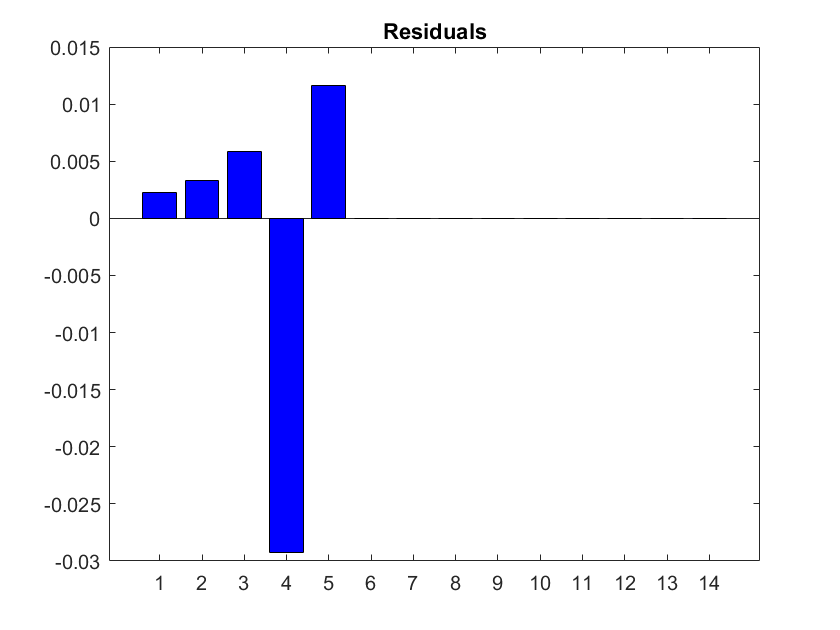



if exist("list_info") && length(list_info)==3
            [X_hat,useless]=normalizeX_(X_hat,"inverse",list_info);
            [X_0,useless]=normalizeX_(X_0,"inverse",list_info);
            Ndeal(X_,X_hat);
end
            
%plotxyc(X,L_dash,eval(F_))
figure
bar(V_hat,"b")
title("Residuals")


%Final check
if abs(L_dash_hat-eval(F_m))<delta
    disp("Good")
else
    disp("Wrong")
end

Good


**Get Result**

%Conversion
if exist("X_i",'var')
    X_hat(X_i)=mod(X_hat(X_i)*200/pi,400);
    S_X(X_i)=S_X(X_i)*200/pi;
end    
if exist("L_i",'var')
    L_0(L_i)=L_0(L_i)*200/pi;
    L_dash_hat(L_i)=mod(L_dash_hat(L_i)*200/pi,400);
    L_hat(L_i)=mod(L_hat(L_i)*200/pi,400);
    S_L_hat(L_i)=S_L_hat(L_i)*200/pi;
    V_hat(L_i)=V_hat(L_i)*200/pi;
    S_v(L_i)=S_v(L_i)*200/pi;
end

disp("=========================")

disp("6.Get Result and S_xx") 

6.Get Result and S_xx


disp("=========================")

format long


disp("Get Unknown X_hat, S_x:") 

Get Unknown X_hat, S_x:


Unknown=arrayfun(@(x) sprintf("%s",x),X_);
table(Unknown,X_0,X_hat,S_X)

ans = 12×4 table
    Unknown        X_0             X_hat                  S_X         
    _______    ___________    ________________    ____________________

     "y1"       5314698.13    5314698.14446477      0.0163603610382104
     "y6"      5317651.428    5317651.42047036       0.019611584121672
     "y9"      5324162.853    5324162.85516914      0.0160825739102996
     "y15"      5320448.85    5320448.84089573      0.0194934798295337
     "x1"       4965804.18    4965804.17367174      0.0151513239683787
     "x6"      4968940.373     4968940.3753084      0.0173941714206963
     "x9"       4970922.16    4970922.15545105      0.0152864218258522
     "x15"      4962997.53    4962997.53856881      0.0205168409864947
     "w1"                0    300.000786288748    0.000351184590351692
     "w6"                0    399.999747394101    0.0003108663526


disp("Get Updated L_hat, S_l:") 

Get Updated L_hat, S_l:


Measurment=arrayfun(@(x) sprintf("%s",x),L_);
table(Measurment,L_0,L_hat,L_dash_hat,S_L_hat,["V_"+(1:length(V_hat))'],V_hat,S_v)

ans = 14×8 table
    Measurment       L_0            L_hat             L_dash_hat             S_L_hat            Var6             V_hat                    S_v         
    __________    _________    ________________    ________________    ____________________    ______    _____________________    ____________________

    "DIS6_1"       4307.851    4307.85327871504    4307.85327871504      0.0319413910099144    "V_1"       0.00227871504004659         0.0247838556534
    "DIS9_1"      10759.852     10759.855306212     10759.855306212      0.0279631560408073    "V_2"        0.0033062119651584      0.0291985250472394
    "DIS9_6"       6806.332    6806.33780900131    6806.33780900131      0.0319623641680638    "V_3"      

**VCE**


if VCE_CONFIG==false       %~exist("Var_ind")
    [Var_ind,Var_name]=findVar();

    for i =1:length(Var_ind)
        P_dist=P_LL(Var_ind{i},Var_ind{i});
        Q_vvP_dist=Q_vvP(Var_ind{i},Var_ind{i});
        %Sub-vectors of residuals
        v_dist = V_hat_rad(Var_ind{i},1);          %sub-vector of v
        %Compute trace for sub-matrices Q_vvP_dist and Q_vvP_dir
        r_dist = trace(Q_vvP_dist);
        s_o_dist(i,1) =sqrt((v_dist'*P_dist*v_dist)/r_dist);
    end

    s_o_all=expand_V(zeros(size(L_)),Var_ind,s_o_dist);
    a_all=expand_V(zeros(size(L_)),Var_ind,1*ones(length(Var_ind),1));
    a_all=a_all.*s_o_all;
    
end
    

try
    disp("Variance Component") 
    a_all_dist=unique(a_all);
    table(Var_name,s_o_dist,a_all_dist) 
catch

    table(Measurment,s_o_all,a_all) 
end

Variance Component


ans = 2×3 table
    Var_name        s_o_dist            a_all_dist    
    ________    _________________    _________________

     "DIS"      0.232367435128917    0.232367435128917
     "DIR"       0.48170206526796     0.48170206526796


**Quality Assessment**

disp("Global test") 

Global test


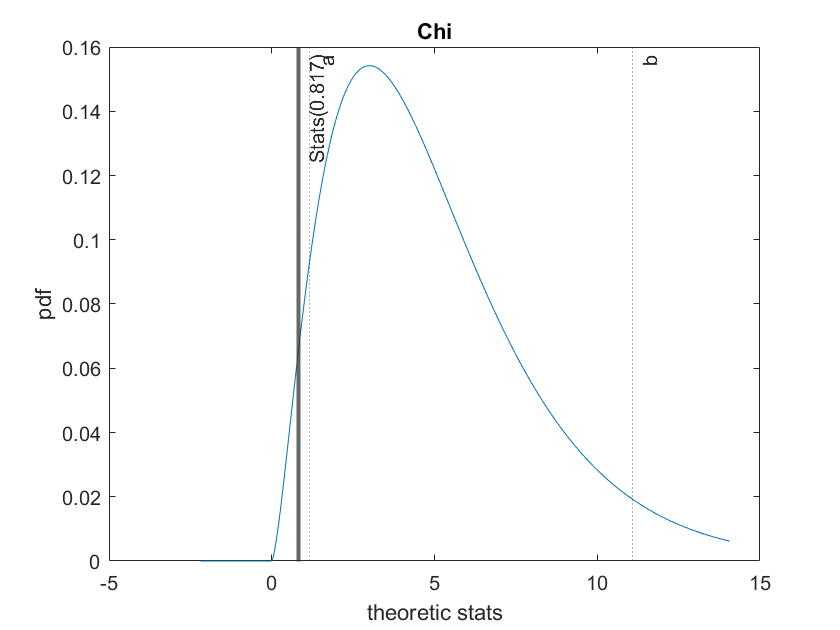

reject the H0, significant smaller then


confidence_tool=confidence_tool();
stats=confidence_tool.statistic_test_chi(0.95, sigma_0, s_0, redundancy);




disp("Internal and external reliability parameters") 

Internal and external reliability parameters



%Check 3σ rule
mat=sqrt(S_L_hat);  

%Compute EV
r_i=diag(Q_vv*P_LL);
EV=r_i*100;

% NV
sigma_v=sigma_0*sqrt(diag(Q_vv));
NV=abs(V_hat_rad)./sigma_v;


for j=1:size(mat)
    % 3 sigma update
    if V_hat_rad(j)>(3*mat(j)) || V_hat_rad(j)<(-3*mat(j))
        sigma3_rule(j,1)="exceed 3sigma";
    else
        sigma3_rule(j,1)="Good";
    end
    % EV update
    if EV(j)<1
        EV_comment(j,1)="not controlled";
    elseif EV(j)<10
        EV_comment(j,1)="poorly controlled";
    elseif EV(j)<30
        EV_comment(j,1)="sufficiently controlled";
    elseif EV(j)<70
        EV_comment(j,1)="good controlled";   
    else
        EV_comment(j,1)="Excellent";   
    end
    
    % NV
    if NV(j)<2.5
        NV_comment(j,1)="no blunder";
    elseif NV(j)<4
        NV_comment(j,1)="blunder possible";
    else
        NV_comment(j,1)="blunder highly";   
    end  
    
end



% Potential magnitude of a blunder
GF=-V_hat_rad./r_i;
 
% Lower boundary value for blunders
GRZW=ones(no_n,1); % help matlab with memory by making a empty matrix
for i=1:no_n
    GRZW(i,1)=sigma_0*4.13/sqrt(r_i(i,1)*P_LL(i,i));
end



GF(L_i,1) = GF(L_i,1)*200/pi;

GRZW(L_i,1)=GRZW(L_i,1)*200/pi;   % we change those measurments that were  amgles


P_diag=diag(P_LL);
dd=ones(size(r_i));
rw=zeros(size(r_i));


for i=1:length(L_i)
    target_name=Measurment(L_i(i));
    target_name=regexp(target_name,'\d*\.?\d*','match');
    num_1=target_name{1};
    num_2=target_name{2};
    
    %get dis
    if exist(["DIS"+num_1+"_"+num_2])
        dd(L_i(i))=eval(["DIS"+num_1+"_"+num_2]);
    elseif exist(["DIS"+num_2+"_"+num_1])
        dd(L_i(i))=eval(["DIS"+num_2+"_"+num_1]);
    else
        warning("there is no "+["DIS"+num_2+"_"+num_1])
        dd(L_i(i))=1;
    end
    Psum_i=find(contains(Measurment,["DIR"+num_1+"_"]));
    PSum=sum(P_diag(Psum_i));
    rw(L_i(i))=P_diag(L_i(i))/PSum;
end

r_i_w=1-r_i;
r_i_w=(r_i_w-rw).*dd;

EP=r_i_w.*GF;

table(Measurment,V_hat_rad,S_L_hat,sigma3_rule,EV,EV_comment,GF,GRZW,NV,NV_comment,EP)

ans = 14×11 table
    Measurment          V_hat_rad                S_L_hat           sigma3_rule           EV                  EV_comment                     GF                     GRZW                    NV             NV_comment              EP         
    __________    _____________________    ____________________    ___________    ________________    _________________________    _____________________    ___________________    __________________    ____________    ____________________

    "DIS6_1"        0.00227871504004659      0.0319413910099144      "Good"       37.5798422885303    "good controlled"            